# Part 7: 連続潮流計算と電力方程式のヤコビアン

負荷が増えると、負荷の側の電圧は下がっていきます。どの系統にも、それ以上は負荷に電力を送れない限界（ノーズ点）があり、運転点がそこに達すると電圧を保てなくなります（電圧崩壊）。この Part では、まず 2 母線の系統で PV カーブとノーズ点の意味を式から確かめ、次に GUILDA の連続潮流計算で IEEE 9 母線系統の PV カーブを描きます。発電機の無効電力の限界でカーブがどう変わるか、ノーズ点で電力方程式のヤコビアンに何が起きるかを、数値で確かめます。

**この Part で分かること**

- PV カーブとノーズ点の式と、無効電力（負荷の力率）がノーズ点を大きく動かす理由

- 連続潮流計算が、負荷のパラメータ $\lambda$ と弧長の条件でノーズ点の先までカーブをたどる仕組み

- 発電機が無効電力の上限に達すると PV 母線が PQ 母線に変わり、ノーズ点が手前に来ること

- ヤコビアンの逆行列が負荷に対する電圧の感度であり、ノーズ点で縮約したヤコビアンの最小固有値が 0 になること

- 電力用コンデンサなどの対策でノーズ点がどれだけ動くか

知識ページ: [Part 7: 連続潮流計算と電力方程式のヤコビアン](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part7-continuation-power-flow.html","-browser")) （クリックするとブラウザで開きます）。知識ページの図は、このライブスクリプトの中のコードで描いています。

**注意:** GUILDA のフォルダがパスに入っている（`GUILDA.addpath` を実行済みの）状態で実行します。全体の実行には 1 分ほどかかります。

図は、知識ページの図と同じ配色と大きさで描きます。色と、図を作るときの設定（白い背景、文字 8 pt）を最初にまとめておきます。

sct_style = struct( ...
    "rr_brand", [0, 89, 167] / 255, ...    % 青（主な系列）
    "rr_c3",    [154, 91, 0] / 255, ...    % 橙（比べる場合）
    "rr_ink",   [27, 33, 39] / 255, ...    % 濃い文字
    "rr_ink2",  [56, 66, 76] / 255, ...    % 軸と文字
    "rr_muted", [90, 101, 112] / 255);     % 補助の線
c_fig = {"Color", "w", "Units", "centimeters", "DefaultAxesFontSize", 8, ...
    "DefaultTextFontSize", 8, "DefaultLegendFontSize", 8, "DefaultLegendFontSizeMode", "manual"};

## 1. 2 母線の系統の PV カーブとノーズ点

### 負荷の電圧の式

いちばん簡単な系統を考えます。発電機が送電端の電圧を $E$ に保ち、リアクタンス $X$ の送電線（抵抗と充電容量は無視）を通して、一定の電力 $P + jQ$ を使う負荷に電力を送ります。負荷の電圧を $V$、その位相が送電端より $\delta$ だけ遅れているとすると（量はすべて単位法）、負荷に届く電力は次のとおりです。


$$P = \frac{EV}{X}\sin\delta, \qquad Q = \frac{EV\cos\delta - V^2}{X}$$


$(PX)^2 + (QX + V^2)^2 = (EV)^2(\sin^2\delta + \cos^2\delta) = E^2V^2$ を使って $\delta$ を消すと、$V^2$ の 2 次方程式になります。


$$V^4 + (2QX - E^2)V^2 + X^2(P^2 + Q^2) = 0 \quad\Longrightarrow\quad V^2 = \frac{E^2}{2} - QX \pm \sqrt{\frac{E^4}{4} - X^2P^2 - E^2XQ}$$


力率が一定の負荷（$Q = P\tan\varphi$）で $P$ を大きくしていくと、この式が PV カーブを描きます。符号 + が上側の枝（電圧が高く電流の小さい解）、符号 − が下側の枝です。

### ノーズ点

平方根の中が 0 になるところで 2 つの解が 1 つになり、その先では実数の解がありません。これがノーズ点（最大負荷点）です。$Q = P\tan\varphi$ を入れて平方根の中を 0 とおくと、$P$ の 2 次方程式から、供給できる最大の有効電力が求まります。


$$P_\mathrm{max} = \frac{E^2}{2X}\left(\sqrt{1 + \tan^2\varphi} - \tan\varphi\right)$$


$E = 1$ pu、$X = 0.5$ pu として、負荷の力率を変えて計算します。

r_E = 1;      % [pu] 送電端の電圧
r_X = 0.5;    % [pu] 送電線のリアクタンス
rv_k = [tan(acos(0.9)), tan(acos(0.95)), 0, -tan(acos(0.95))];   % Q/P = tan(phi)：0.9 遅れ、0.95 遅れ、1、0.95 進み
rv_Pmax = r_E^2 * (sqrt(1 + rv_k.^2) - rv_k) / (2 * r_X)        % [pu] ノーズ点の P

rv_Pmax =     0.6268    0.7239    1.0000    1.3813


rv_Vnose = sqrt(r_E^2 / 2 - rv_k .* rv_Pmax * r_X)              % [pu] ノーズ点の V

rv_Vnose =     0.5901    0.6173    0.7071    0.8526


3 本の PV カーブを、上の式から描きます（知識ページの「無効電力が大切な理由」の図）。実線が上側の枝、破線が下側の枝、点がノーズ点です。

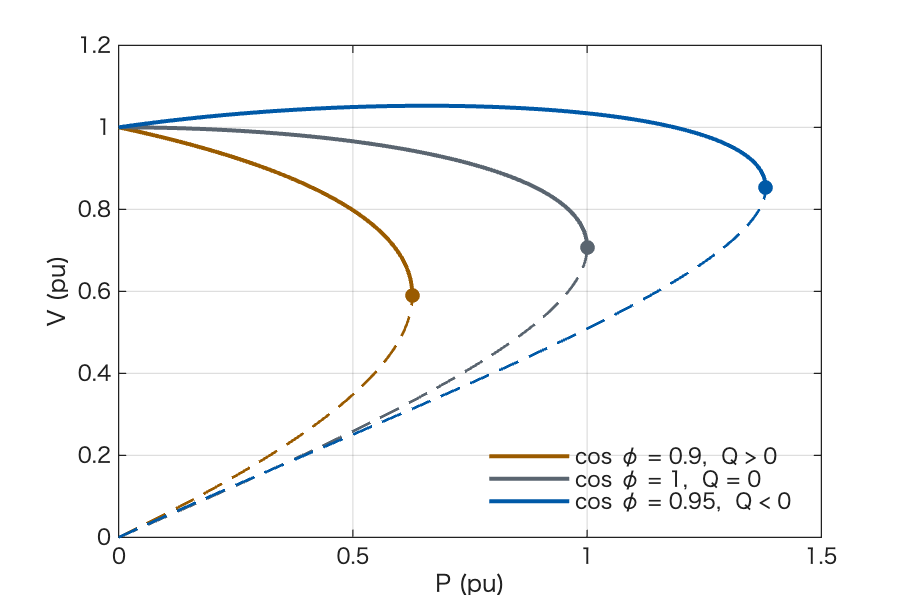

rr_k = rv_k([1, 3, 4])';
sr_name = ["cos φ = 0.9,  Q > 0", "cos φ = 1,  Q = 0", "cos φ = 0.95,  Q < 0"];
fig = figure(c_fig{:}, Position=[2, 2, 12, 8]);
ax = axes(fig, XLim=[0, 1.5], YLim=[0, 1.2], NextPlot="add", XGrid="on", YGrid="on", Box="on");
rm_color = [sct_style.rr_c3; sct_style.rr_muted; sct_style.rr_brand];
a_line = gobjects(1, numel(rr_k));
for i_case = 1:numel(rr_k)
    r_k = rr_k(i_case);
    r_Pmax = r_E^2 * (sqrt(1 + r_k^2) - r_k) / (2 * r_X);
    rv_P = r_Pmax * (1 - linspace(1, 0, 400)'.^2);   % ノーズ点の近くを細かく
    rv_root = sqrt(max(r_E^4 / 4 - r_X^2 * rv_P.^2 - r_E^2 * r_X * r_k * rv_P, 0));
    rv_Vup = sqrt(r_E^2 / 2 - r_k * rv_P * r_X + rv_root);
    rv_Vlow = sqrt(r_E^2 / 2 - r_k * rv_P * r_X - rv_root);
    a_line(i_case) = plot(ax, rv_P, rv_Vup, Color=rm_color(i_case, :), LineWidth=1.5, DisplayName=sr_name(i_case));
    plot(ax, rv_P, rv_Vlow, "--", Color=rm_color(i_case, :), LineWidth=1);
    plot(ax, r_Pmax, sqrt(r_E^2 / 2 - r_k * r_Pmax * r_X), "o", MarkerSize=5, ...
        MarkerFaceColor=rm_color(i_case, :), MarkerEdgeColor=rm_color(i_case, :));
end
xlabel(ax, "P (pu)");
ylabel(ax, "V (pu)");
legend(ax, a_line, Location="southeast", Box="off");

**考察:**

- 電圧は、はじめはゆっくり、やがて急に下がります。電圧の下がり方が小さく見えても、限界の近くにいることがあります。

- 同じ負荷に対して解が 2 つあります。系統は電流の小さい上側の枝で運転します。2 つの解はノーズ点で 1 つになります。

- 限界があるのは、負荷を増やすと電流は増えますが、増えた電流が送電線で電圧を下げるからです。ノーズ点では 2 つの効果が打ち消し合い、それ以上の電力を送れません。

- 無効電力を使う負荷（0.9 遅れ）では、ノーズ点は 0.63 pu まで下がります。無効電力をその場で少し出す負荷（0.95 進み）では 1.38 pu で、2 倍以上の有効電力を送れます。ノーズ点の位置は、無効電力で大きく変わります。

### 無効電力が電圧を決める

位相差が小さいとき（$\cos\delta \approx 1$）、上の $Q$ の式は次のように近似できます。


$$Q \approx \frac{V}{X}(E - V)$$


負荷に無効電力を届けるには、負荷の電圧が送電端より低くなければなりません。負荷が使う無効電力が多いほど、電圧は下がります。さらに、送電線そのものがリアクタンスで無効電力（電流の 2 乗に比例）を消費するので、無効電力は遠くへ送りにくい電力です。電圧崩壊に対する余裕が「無効電力の問題」といわれ、運転では発電機などがあとどれだけ無効電力を出せるか（無効電力の予備力）を見ているのはこのためです。

## 2. 連続潮流計算で IEEE 9 母線系統の PV カーブを描く

### 仕組み

PV カーブは、負荷を少しずつ増やしながら潮流計算を何度も解けば描けそうです。しかし、ノーズ点の近くではニュートン法の傾き（ヤコビアン）がある向きにほとんど平らになり、一歩一歩が当てにならなくなります。ノーズ点の先には解がないので、下側の枝にはたどり着けません。

連続潮流計算（CPF）は、選んだ負荷母線 $i$ の負荷を 1 つのパラメータ $\lambda$ で大きくしていきます。出発点（$\lambda = 0$）の負荷を $P_{\mathrm{L}i}^0$、$Q_{\mathrm{L}i}^0$ として、


$$P_{\mathrm{L}i}(\lambda) = (1+\lambda)P_{\mathrm{L}i}^0, \qquad Q_{\mathrm{L}i}(\lambda) = (1+\lambda)Q_{\mathrm{L}i}^0$$


とし、$\lambda$ も未知数の 1 つとして扱います。電力方程式 $f(\theta, V, \lambda) = 0$ は式より未知数が 1 つ多くなり、その解は 1 本の曲線（経路）になります。経路に沿った 1 歩は、曲線の向きに進んで次の点を見積もる予測子と、その点をニュートン法で曲線の上に戻す修正子からなります。未知数をまとめて $x = (\theta, V, \lambda)$、今の点を $x_k$、歩幅を $h$ とすると、修正子が解く式は次のとおりです。


$$f(x) = 0, \qquad \lVert x - x_k \rVert^2 = h^2$$


2 つ目の式（弧長の条件）が、「負荷を決める」条件の代わりです。今の点から決まった距離にある点を探すので、ノーズ点でも答えが 1 つに決まり、先端で向きを変えて下側の枝へ進めます。

### 実行する

同梱の IEEE 9 母線系統を読み込み、`initialize` で平衡点を求めます。連続潮流計算は、この平衡点から出発します。負荷は母線 5・6・8 にあり、これを `LoadBus` に指定して同じ倍率 $(1 + \lambda)$ で大きくしていきます。

net = network.IEEE9bus();
[rm_init, flag_init] = net.initialize();
flag_init

flag_init = 1

sv_load = ["B005", "B006", "B008"];
tic
[result, flag_cpf] = net.calculate_continuation_powerflow(LoadBus=sv_load);
toc

経過時間は 3.066798 秒です。


flag_cpf

flag_cpf = logical
   1


lambda_max = result.r_lambdaMax

lambda_max = 1.3739

`flag_cpf` が 1 なら、ノーズ点を越えて下側の枝まで経路をたどれています。結果は `ResultCPF` で、`rv_lambda` が経路の各点の $\lambda$、`cm_Vbus` が各点の母線電圧（複素数）、`r_lambdaMax` がノーズ点の $\lambda$ です。$\lambda_\mathrm{max} \approx 1.374$ なので、負荷は元の約 2.37 倍まで増やせます。

`plot_pvcurve` で、負荷母線の電圧の大きさを $\lambda$ に対して描きます（知識ページの「IEEE 9 母線系統の PV カーブ」の図）。破線がノーズ点です。

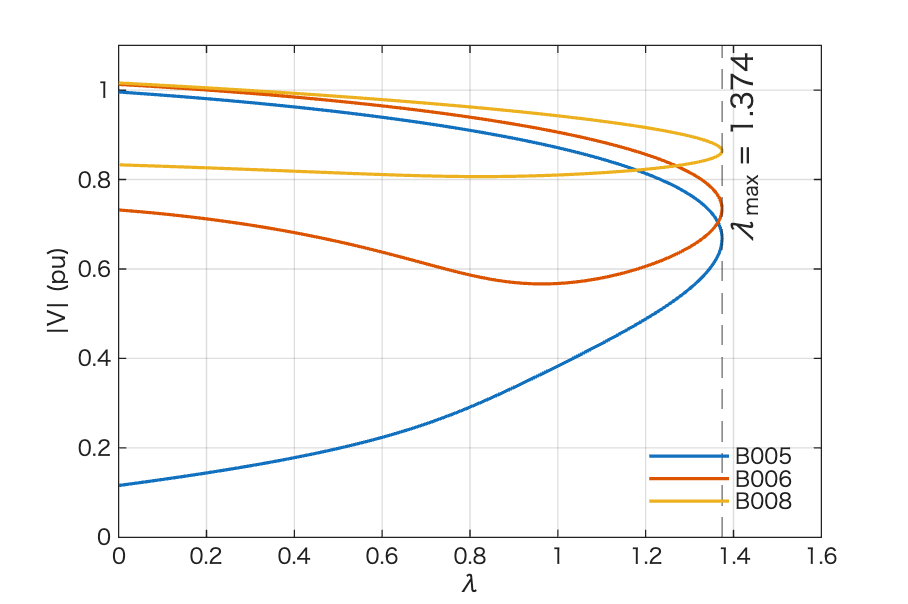

fig = figure(c_fig{:}, Position=[2, 2, 12, 8]);
ax = axes(fig);
result.plot_pvcurve(Parent=ax);
title(ax, "");
xlabel(ax, "λ");
ylabel(ax, "|V| (pu)");
set(ax, FontSize=8, XLim=[0, 1.6], YLim=[0, 1.1], XGrid="on", YGrid="on", Box="on");
set(ax.Legend, Location="southeast", Box="off");

ノーズ点での母線電圧は `tab_nose` にまとまっています。出発点の電圧の大きさと並べます（B001〜B009 の順）。出発点の電圧は、`initialize` の 1 番目の出力（母線ごとの行。1 列目が電圧フェーザ）にあります。

V_start = abs(rm_init(:, 1))'

V_start =     1.0400    1.0250    1.0250    1.0258    0.9956    1.0127    1.0258    1.0159    1.0324


V_nose = result.tab_nose.V'

V_nose =     1.0400    1.0250    1.0250    0.8088    0.6691    0.7353    0.9087    0.8642    0.9323


**考察:** どの曲線もノーズ点まで進み、下側の枝を戻ってきます。電圧がいちばん大きく下がるのは負荷の最も大きい母線 5 で、ノーズ点では約 0.67 pu です。母線 5 がこの系統の弱い所です。発電機のある母線 1〜3 は、発電機が必要なだけ無効電力を出して電圧を保つので、ノーズ点でも元の電圧のままです（この計算では、発電機の無効電力に上限を設けていません）。

### ふつうの潮流計算と比べる

ふつうの潮流計算では、本当にノーズ点の先で解けなくなるのでしょうか。3 つの負荷の電力（パラメータの `powerflow` のグループの `P` と `Q`）を同じ倍率にして、潮流計算を解きます。ノーズ点の少し手前（2.37 倍）と少し先（2.38 倍）を比べます。

tab_load0 = net.get_parameter("powerflow", Class="component.load.abstract")   % 元の負荷

tab_load0 = 3×2 table
                  P        Q  
                _____    _____

    B005LRX1    -1.25     -0.5
    B006LRX1     -0.9     -0.3
    B008LRX1       -1    -0.35


for r_scale = [2.37, 2.38]
    tab_load = tab_load0;
    tab_load.P = r_scale * tab_load0.P;
    tab_load.Q = r_scale * tab_load0.Q;
    net.set_parameter("powerflow", tab_load);
    [resPF, flag_pf] = net.calculate_powerflow(Progress="none");
    fprintf("負荷 %.2f 倍: flag = %d\n", r_scale, flag_pf);
end

負荷 2.37 倍: flag = 1


負荷 2.38 倍: flag = -2


net.set_parameter("powerflow", tab_load0);   % 負荷を元に戻す
net.initialize();   % 平衡点を求め直す（値は元と同じ）

潮流計算の条件を書き換えると、元の値に戻しても系統は「平衡点が古い」という扱いになるので、最後に `initialize` をやり直しています。潮流計算は既定では最後に収束した解から出発します（`WarmStart`）。ここではそれがノーズ点のすぐ手前の 2.37 倍の解で、ヤコビアンが特異に近いその点からはニュートン法がうまく進みません。そのように前の解からの計算が失敗すると、GUILDA は平らな初期値（電圧 1 pu、角度 0）から 1 回だけ自動で解き直すので、元の負荷の解が求まります。

2\.37 倍では解が求まり（`flag = 1`）、2.38 倍では解がないので収束しません（警告が出て `flag = -2`）。2.38 倍の計算は 2.37 倍の解から出発し、失敗したあと平らな初期値からも解き直していますが、どちらからも解は見つかりません。ふつうの潮流計算で見つけた限界は、連続潮流計算のノーズ点（2.374 倍）と一致します。ただし、ふつうの潮流計算では「解けなくなった」ことしか分からず、それがノーズ点を越えたためか、計算がうまくいかなかったためかを区別できません。連続潮流計算は、限界の位置と、その手前でカーブがどう曲がっていくかまで示します。

## 3. 発電機の無効電力の限界

発電機は、必要なだけ無効電力を出して端子の電圧を一定に保ちます。そのため潮流計算ではその母線を PV 母線として扱います。しかし、発電機が出せる無効電力には、界磁や電機子の巻線の発熱で決まる限界があります。限界に達すると電圧を保てなくなり、無効電力は限界の値のままになって、その母線は PQ 母線に変わります。そこから先は電圧が速く下がり、ノーズ点も手前に来ます。

発電機の運転制約（パラメータの `operation` のグループ）の `Qmin`・`Qmax` は、既定では `-Inf`・`Inf`（制約なし）です。母線 2 と 3 の発電機の `Qmax` に 0.6 pu を設定します（この例のために仮に決めた値です）。slack の母線 1 の発電機には上限を設けません。運転制約を変えても平衡点は変わらないので、`initialize` をやり直す必要はありません。

tab_gen = net.get_parameter("operation", Key="gen-1axis");
tab_gen{["B002SG1", "B003SG1"], "Qmax"} = 0.6;
net.set_parameter("operation", tab_gen);
net.get_parameter("operation", Key="gen-1axis")

ans = 3×5 table
               baseMVA    Pmin    Pmax    Qmin    Qmax
               _______    ____    ____    ____    ____

    B001SG1      100      -Inf    Inf     -Inf    Inf 
    B002SG1      100      -Inf    Inf     -Inf    0.6 
    B003SG1      100      -Inf    Inf     -Inf    0.6 


`Limits="Q"` を指定すると、発電機の無効電力が上限に達した時点で、その母線を PV 母線から PQ 母線に切り替えて経路をたどり続けます。

result_Q = net.calculate_continuation_powerflow(LoadBus=sv_load, Limits="Q");
result_Q.tab_switch

ans = 2×5 table
    lambda     Step     Bus      Limit     Bound
    _______    ____    ______    ______    _____

    0.74096     37     "B002"    "Qmax"     0.6 
    0.86588     45     "B003"    "Qmax"     0.6 


`tab_switch` に、切り替わった母線と、そのときの $\lambda$・経路の歩数（`Step`）・上限の種類と値が並びます。$\lambda \approx 0.74$ で発電機 2 が、$\lambda \approx 0.87$ で発電機 3 が上限 0.6 pu に達しています。

上限なし・上限ありの PV カーブを並べて描きます（知識ページの「無効電力の限界」の図）。(b) では、切り替わった点を母線 5 の曲線の上に印で示します。`plot_pvcurve` はこの印を描かないので、`plot` で加えます。

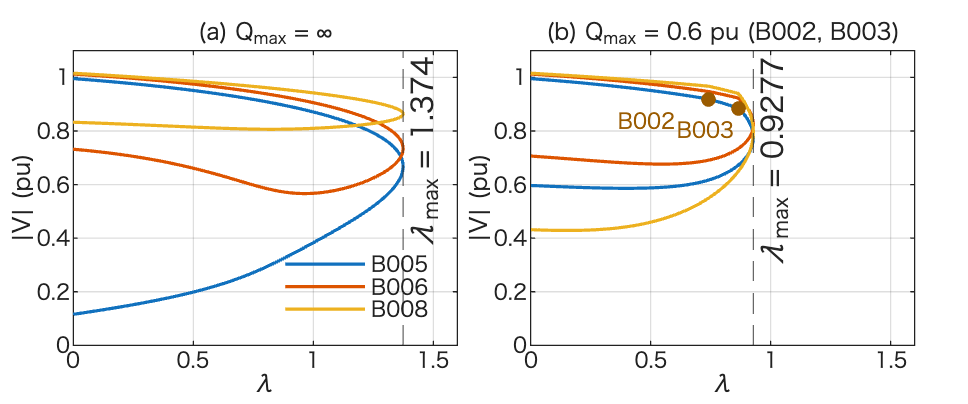

fig = figure(c_fig{:}, Position=[2, 2, 18, 7.5]);
tl = tiledlayout(fig, 1, 2, TileSpacing="compact", Padding="compact");
a_res = {result, result_Q};
sr_title = ["(a) Q_{max} = ∞", "(b) Q_{max} = 0.6 pu (B002, B003)"];
a_ax = gobjects(1, 2);
for i_case = 1:2
    a_ax(i_case) = nexttile(tl);
    a_res{i_case}.plot_pvcurve(Parent=a_ax(i_case));
    title(a_ax(i_case), sr_title(i_case), FontWeight="normal");
    xlabel(a_ax(i_case), "λ");
    ylabel(a_ax(i_case), "|V| (pu)");
end
linkaxes(a_ax, "xy");
set(a_ax, FontSize=8, XLim=[0, 1.6], YLim=[0, 1.1], XGrid="on", YGrid="on", Box="on");
legend(a_ax(2), "off");
set(a_ax(1).Legend, Location="southeast", Box="off");
ax = a_ax(2);
hold(ax, "on");
i_5 = result_Q.sv_bus == "B005";
iv_step = result_Q.tab_switch.Step;
plot(ax, result_Q.rv_lambda(iv_step), abs(result_Q.cm_Vbus(i_5, iv_step)), "o", MarkerSize=5, ...
    MarkerFaceColor=sct_style.rr_c3, MarkerEdgeColor=sct_style.rr_c3, HandleVisibility="off");
rr_dx = -0.02 - 0.12 * ((numel(iv_step):-1:1) - 1);   % 先に切り替わった点のラベルをより左に
text(ax, result_Q.rv_lambda(iv_step) + rr_dx, abs(result_Q.cm_Vbus(i_5, iv_step)) - 0.04, ...
    result_Q.tab_switch.Bus, HorizontalAlignment="right", VerticalAlignment="top", Color=sct_style.rr_c3);
hold(ax, "off");

2 つのノーズ点の負荷倍率と、そこでの母線 5 の電圧を並べます（左が上限なし、右が上限あり）。

ratio_nose = 1 + [result.r_lambdaMax, result_Q.r_lambdaMax]

ratio_nose =     2.3739    1.9277


V5_nose = [result.tab_nose{"B005", "V"}, result_Q.tab_nose{"B005", "V"}]

V5_nose =     0.6691    0.7785


**考察:**

- 最初に切り替わる点（$\lambda \approx 0.74$）までは、2 本の曲線は重なっていて違いが見えません。切り替わるたびに曲線が折れ曲がって速く下がり、供給できる負荷の上限は約 2.37 倍から約 1.93 倍に下がります。無効電力の限界を考えない PV カーブは、電圧崩壊までの余裕を大きく見積もってしまいます。

- 上限ありのノーズ点での母線 5 の電圧（約 0.78 pu）は、上限なし（約 0.67 pu）より高くなっています。電圧の値だけを見ていると、限界の近さに気づきにくいことが分かります。

- 上限の値を変えると、切り替わる $\lambda$ とノーズ点が動きます。`Qmax` を大きくすると上限なしの曲線に近づき、小さくするとノーズ点がさらに手前に来ます。

**注意:** `Limits` には `"Q"` のほか、母線電圧の上下限で経路を打ち切る `"V"`、ブランチの容量で打ち切る `"S"`、すべてを使う `"all"` を指定できます（既定は `"none"`）。1 歩の大きさは `StepSize` と `ArcLength` で決まります。呼び出しで渡した `LoadBus` は、その呼び出しにだけ効きます。毎回の指定を省きたいときは、`net.solver_CPF.LoadBus = sv_load;` のように設定しておくと、以降の呼び出しの既定値になります。

## 4. ヤコビアンは感度

### 傾きの行列

潮流計算のニュートン法は、電力方程式のヤコビアンを使います。各母線の位相角や電圧の大きさを少し変えたとき、各母線の有効電力と無効電力がどれだけ変わるかを並べた、傾きの行列です。


$$\begin{bmatrix}\Delta P\\ \Delta Q\end{bmatrix} = J \begin{bmatrix}\Delta \theta\\ \Delta V\end{bmatrix}, \qquad J = \begin{bmatrix} J_{P\theta} & J_{PV}\\ J_{Q\theta} & J_{QV}\end{bmatrix} = \begin{bmatrix} \partial P/\partial\theta & \partial P/\partial V\\ \partial Q/\partial\theta & \partial Q/\partial V\end{bmatrix}$$


$\Delta P$ は slack 以外の各母線に注入される有効電力の、$\Delta Q$ は PQ 母線に注入される無効電力の小さな変化、$\Delta\theta$ と $\Delta V$ は同じ母線の電圧の位相角と大きさの変化です（テイラー展開の 1 次の項なので、変化が小さいときだけ成り立ちます）。$J$ に逆行列があれば、逆向きにも読めます。


$$\begin{bmatrix}\Delta \theta\\ \Delta V\end{bmatrix} = J^{-1} \begin{bmatrix}\Delta P\\ \Delta Q\end{bmatrix}$$


こう読むと、$J^{-1}$ は負荷を少し変えたときに電圧がどれだけ変わるかという感度です。PV カーブの上では、これは曲線の傾きです。

### 2 母線の系統で傾きを見る

1 節の 2 母線の系統（力率 0.95 遅れ）では、上側の枝は $g(V, P) = V^4 + (2QX - E^2)V^2 + X^2(P^2 + Q^2) = 0$（$Q = P\tan\varphi$）を満たします。陰関数の微分から、曲線の傾きは次のとおりです。


$$\frac{\mathrm{d}V}{\mathrm{d}P} = -\frac{\partial g/\partial P}{\partial g/\partial V} = -\frac{2X\tan\varphiV^2 + 2X^2(1 + \tan^2\varphi)P}{4V^3 + 2(2XP\tan\varphi - E^2)V}$$


ノーズ点では分母の $\partial g/\partial V$ が 0 になり、傾きは $-\infty$（接線が垂直）になります。$P = 0.3$、0.55、0.7 pu で接線を描きます（知識ページの「ヤコビアンは感度」の図）。

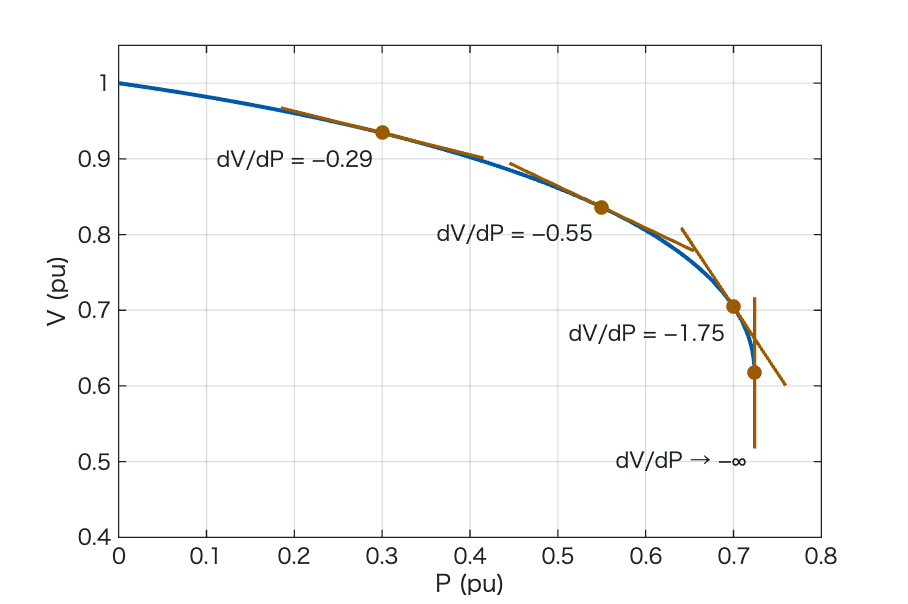

r_k = tan(acos(0.95));
r_Pmax = r_E^2 * (sqrt(1 + r_k^2) - r_k) / (2 * r_X);
f_Vup = @(P) sqrt(r_E^2 / 2 - r_k * P * r_X + sqrt(max(r_E^4 / 4 - r_X^2 * P.^2 - r_E^2 * r_X * r_k * P, 0)));
f_slope = @(P, V) -(2 * r_k * r_X * V.^2 + 2 * r_X^2 * P * (1 + r_k^2)) ./ ...
    (4 * V.^3 + 2 * (2 * r_k * P * r_X - r_E^2) .* V);
rv_P = r_Pmax * (1 - linspace(1, 0, 400)'.^2);
rr_Pt = [0.3, 0.55, 0.7];   % [pu] 接線を引く点
r_Vnose = sqrt(r_E^2 / 2 - r_k * r_Pmax * r_X);
fig = figure(c_fig{:}, Position=[2, 2, 12, 8]);
ax = axes(fig, XLim=[0, 0.8], YLim=[0.4, 1.05], NextPlot="add", XGrid="on", YGrid="on", Box="on");
plot(ax, rv_P, f_Vup(rv_P), Color=sct_style.rr_brand, LineWidth=1.5);
for r_P = rr_Pt
    r_V = f_Vup(r_P);
    r_s = f_slope(r_P, r_V);
    rv_dP = [-0.12, 0.12] / sqrt(1 + r_s^2);
    plot(ax, r_P + rv_dP, r_V + r_s * rv_dP, Color=sct_style.rr_c3, LineWidth=1.2);
    plot(ax, r_P, r_V, "o", MarkerSize=5, MarkerFaceColor=sct_style.rr_c3, MarkerEdgeColor=sct_style.rr_c3);
    text(ax, r_P - 0.01, r_V - 0.02, sprintf("dV/dP = %s%.2f", char(8722), abs(r_s)), ...
        HorizontalAlignment="right", VerticalAlignment="top", Color=sct_style.rr_ink);
end
plot(ax, [r_Pmax, r_Pmax], r_Vnose + [-0.1, 0.1], Color=sct_style.rr_c3, LineWidth=1.2);
plot(ax, r_Pmax, r_Vnose, "o", MarkerSize=5, MarkerFaceColor=sct_style.rr_c3, MarkerEdgeColor=sct_style.rr_c3);
text(ax, r_Pmax - 0.01, r_Vnose - 0.1, "dV/dP → −∞", HorizontalAlignment="right", ...
    VerticalAlignment="top", Color=sct_style.rr_ink);
xlabel(ax, "P (pu)");
ylabel(ax, "V (pu)");

**考察:** 傾き（負荷に対する電圧の感度）は、$P = 0.3$ pu で −0.29、0.55 pu で −0.55、0.7 pu で −1.75 です。ノーズ点から遠い所では、負荷が 0.1 pu 増えても電圧は 0.03 pu ほどしか動きませんが、ノーズ点の近くでは同じ増加で 0.17 pu 以上動きます。ノーズ点では、負荷をほんの少し増やすだけで、電圧が限りなく大きく変わらなければなりません。

## 5. 縮約したヤコビアンと、ノーズ点での特異性

### V–Q 感度

大きな系統では、同じ情報がヤコビアンに入っています。電圧を調べるときは、有効電力を変えない（$\Delta P = 0$）とすることがよくあります。すると 1 行目のブロックから $\Delta\theta = -J_{P\theta}^{-1}J_{PV}\Delta V$ となり、$\Delta\theta$ を消すと、$\Delta Q$ と $\Delta V$ の間の小さな行列（縮約したヤコビアン $J_\mathrm{R}$）が残ります。


$$\Delta Q = J_\mathrm{R}\Delta V, \qquad J_\mathrm{R} = J_{QV} - J_{Q\theta}J_{P\theta}^{-1}J_{PV}$$


$J_\mathrm{R}^{-1}$ の対角要素は、ある母線の無効電力を変えたときの、その母線の電圧の変化（V–Q 感度）です。

### ヤコビアンを作る

GUILDA の連続潮流計算の結果には、経路の各点の母線電圧 `cm_Vbus` が入っています。そこからヤコビアンを MATLAB で作ります（ヤコビアンを返すのは GUILDA の機能ではないので、ここで計算します）。母線電圧のベクトルを $V$、アドミタンス行列を $Y$、注入電流を $I = YV$ とすると、各母線に注入される複素電力 $S = P + jQ$ とその微分は次のとおりです（$\mathrm{diag}$ はベクトルを対角に並べた行列、上の横線は複素共役）。


$$S = \mathrm{diag}(V)\overline{I}, \qquad \frac{\partial S}{\partial \theta} = j\mathrm{diag}(V)\overline{\left(\mathrm{diag}(I) - Y\mathrm{diag}(V)\right)}, \qquad \frac{\partial S}{\partial |V|} = \mathrm{diag}(V)\overline{Y\mathrm{diag}(V/|V|)} + \overline{\mathrm{diag}(I)}\mathrm{diag}(V/|V|)$$


$J_{P\theta}$ と $J_{PV}$ はその実部、$J_{Q\theta}$ と $J_{QV}$ は虚部です。$P$ の行と $\theta$ の列は slack 以外のすべての母線、$Q$ の行と $|V|$ の列は PQ 母線だけを取ります。この計算は、このライブスクリプトの最後にある関数 `reduced_jacobian` にまとめてあります。

tab_Y = net.get_admittance_matrix();
cm_Y = tab_Y{:, :};
sr_bus = string(tab_Y.Properties.VariableNames);
tab_pf = net.get_pf_condition().Bus;    % 母線の種類（Type）

Bus
             Type      Varg      V        P        Q  
            _______    ____    _____    _____    _____

    B001    "slack"      0      1.04      NaN      NaN
    B002    "PV"       NaN     1.025     1.63      NaN
    B003    "PV"       NaN     1.025     0.85      NaN
    B004    "PQ"       NaN       NaN        0        0
    B005    "PQ"       NaN       NaN    -1.25     -0.5
    B006    "PQ"       NaN       NaN     -0.9     -0.3
    B007    "PQ"       NaN       NaN        0        0
    B008    "PQ"       NaN       NaN       -1    -0.35
    B009    "PQ"       NaN       NaN        0        0



assert(isequal(string(tab_pf.Properties.RowNames), sr_bus(:)), "母線の順序が違います。");
sr_type = tab_pf.Type;
lv_ns = sr_type ~= "slack";    % slack 以外の母線

上限なしの経路（2 節）で、元の負荷（$\lambda = 0$）、2 倍（$\lambda = 1$）、2.35 倍（$\lambda = 1.35$）の点の、母線 5 の V–Q 感度を求めます。経路の上側の枝（ノーズ点まで）から、$\lambda$ がいちばん近い点を選びます。

lv_PQ = sr_type == "PQ";
i_nose = find(result.rv_lambda == result.r_lambdaMax, 1);
rv_lam = [0, 1, 1.35];
rv_sens = zeros(size(rv_lam));
for i_l = 1:numel(rv_lam)
    [~, i_step] = min(abs(result.rv_lambda(1:i_nose) - rv_lam(i_l)));
    cm_S = inv(reduced_jacobian(result.cm_Vbus(:, i_step), cm_Y, lv_ns, lv_PQ));    % J_R の逆行列
    i_5 = find(sr_bus(lv_PQ) == "B005");
    rv_sens(i_l) = cm_S(i_5, i_5);
end
load_ratio = 1 + rv_lam

load_ratio =     1.0000    2.0000    2.3500


dVdQ_B005 = rv_sens       % [pu/pu]

dVdQ_B005 =     0.0907    0.1291    0.3742


**考察:** 母線 5 で無効電力を 1 pu 増やしたときの電圧の変化は、元の負荷で約 0.09 pu、2 倍で約 0.13 pu、2.35 倍で約 0.37 pu です。限界の近くでは、同じ無効電力の乱れで、電圧が 4 倍も動きます。

### 最小固有値がノーズ点で 0 になる

感度が無限大になるということは、$J^{-1}$ が存在しない、つまりヤコビアンがノーズ点で特異になるということです。ふつうの潮流計算がノーズ点で失敗するのもこのためです。行列が特異にどれだけ近いかは、固有値で測れます。$J_{P\theta}$ に逆行列がある限り、行列式と $J_\mathrm{R}$ の固有値 $\mu_i$ の間には次の関係があります。


$$\det J = \det J_{P\theta}\cdot\det J_\mathrm{R}, \qquad \det J_\mathrm{R} = \prod_i \mu_i$$


$J$ が特異になるのは、$J_\mathrm{R}$ の固有値のどれかが 0 になるときです。2 つの経路（上限なし・上限あり）のすべての点で $J_\mathrm{R}$ を作り、固有値の実部の最小値 $\mu_\mathrm{min}$ を $\lambda$ に対して描きます（知識ページの「ノーズ点で特異になる」の図）。上限ありの経路では、`tab_switch` の歩数から先で、切り替わった母線を PQ 母線として扱います。

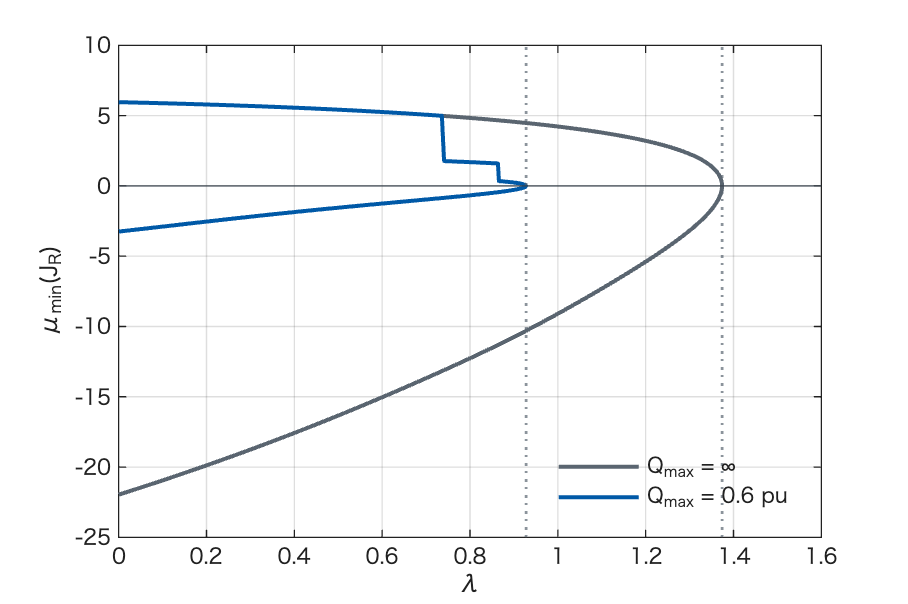

fig = figure(c_fig{:}, Position=[2, 2, 12, 8]);
ax = axes(fig, XLim=[0, 1.6], NextPlot="add", XGrid="on", YGrid="on", Box="on");
rm_color = [sct_style.rr_muted; sct_style.rr_brand];
sr_name = ["Q_{max} = ∞", "Q_{max} = 0.6 pu"];
for i_case = 1:2
    res = a_res{i_case};
    n_step = numel(res.rv_lambda);
    rv_eig = nan(1, n_step);
    for i_step = 1:n_step
        lv_PQ = sr_type == "PQ";
        for i_sw = 1:height(res.tab_switch)
            if res.tab_switch.Step(i_sw) <= i_step
                lv_PQ(sr_bus == res.tab_switch.Bus(i_sw)) = true;
            end
        end
        rv_eig(i_step) = min(real(eig(reduced_jacobian(res.cm_Vbus(:, i_step), cm_Y, lv_ns, lv_PQ))));
    end
    plot(ax, res.rv_lambda, rv_eig, Color=rm_color(i_case, :), LineWidth=1.5, DisplayName=sr_name(i_case));
    xline(ax, res.r_lambdaMax, ":", Color=sct_style.rr_muted, LineWidth=1, HandleVisibility="off");
end
yline(ax, 0, Color=sct_style.rr_ink2, LineWidth=0.6, HandleVisibility="off");
xlabel(ax, "λ");
ylabel(ax, "μ_{min}(J_R)");
legend(ax, Location="southeast", Box="off");

**考察:**

- $\mu_\mathrm{min}$ は上側の枝では正で、負荷が増えるにつれて小さくなり、ちょうどノーズ点（点線）で 0 になって、下側の枝では負になります。ノーズ点、最大の負荷、ふつうの潮流計算が解けなくなる点、ヤコビアンが特異になる点は、すべて同じ 1 つの点です。

- 無効電力の上限がある場合は、PV から PQ に切り替わるたびに $\mu_\mathrm{min}$ が急に下がります。電圧を支えていた発電機が、支えるのをやめるからです。

- 最小固有値は、電圧そのものがまだ問題なく見える間も、ノーズ点に近づくにつれて着実に小さくなるので、余裕の指標として使えます。ここでの固有値は、Part 5 の線形化した動的なモデルの固有値とは別のもので、無効電力の変化に対して電圧がどれだけ踏みとどまるか（硬さ）を表します。

## 6. 電圧を支える対策：電力用コンデンサ

ノーズ点の位置は無効電力で大きく決まるので、いちばんの対策は、負荷の近くで無効電力を供給することです（調相設備）。いちばん簡単なのは、負荷の母線に付けるサセプタンス $B_\mathrm{C}$ の電力用コンデンサで、次の無効電力を供給します。


$$Q_\mathrm{C} = B_\mathrm{C}V^2$$


送電線が運ぶ無効電力は $Q - B_\mathrm{C}V^2$ になるので、1 節の式の $Q$ をこれに置き換えると、2 母線の系統では次の関係になります。


$$X^2P^2 + \left((Q - B_\mathrm{C}V^2)X + V^2\right)^2 = E^2V^2$$


$V$ を決めるとこれは $P$ の 2 次方程式なので、その正の根から、上側と下側の両方の枝が描けます。$B_\mathrm{C} = 0$ と 0.3 pu を比べます（知識ページの「電圧を支える対策」の図）。

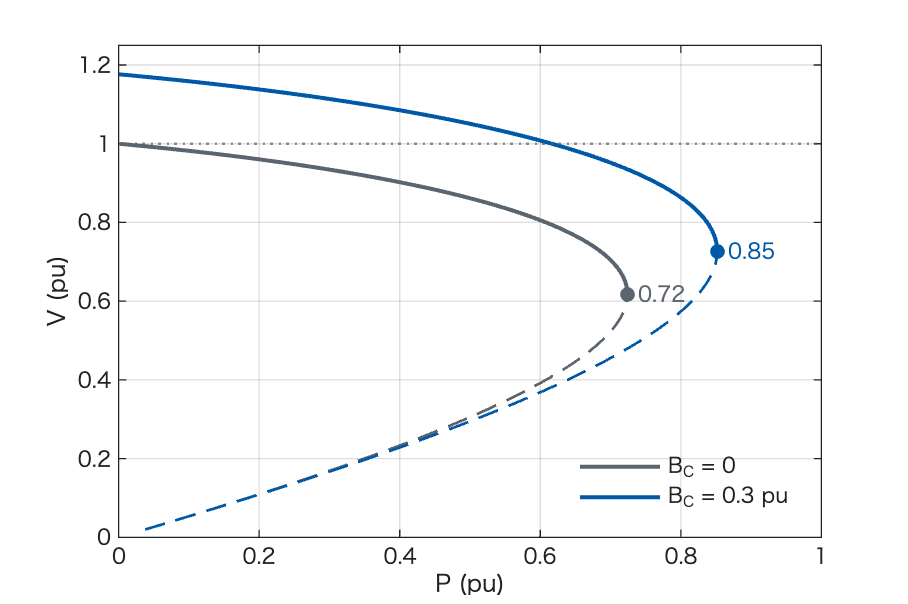

r_k = tan(acos(0.95));
rr_B = [0, 0.3];   % [pu] コンデンサのサセプタンス
sr_name = ["B_C = 0", "B_C = 0.3 pu"];
fig = figure(c_fig{:}, Position=[2, 2, 12, 8]);
ax = axes(fig, XLim=[0, 1], YLim=[0, 1.25], NextPlot="add", XGrid="on", YGrid="on", Box="on");
rm_color = [sct_style.rr_muted; sct_style.rr_brand];
a_line = gobjects(1, 2);
for i_case = 1:2
    rv_V = linspace(0.02, 1.3, 2000)';
    rv_a = rv_V.^2 * (1 - rr_B(i_case) * r_X);       % V^2 - B_C V^2 X
    r_A = r_X^2 * (1 + r_k^2);
    rv_B = 2 * r_k * r_X * rv_a;
    rv_C = rv_a.^2 - r_E^2 * rv_V.^2;
    rv_disc = rv_B.^2 - 4 * r_A * rv_C;
    rv_P = (-rv_B + sqrt(rv_disc)) / (2 * r_A);
    lv_ok = rv_disc >= 0 & rv_P >= 0;
    rv_V = rv_V(lv_ok);
    rv_P = rv_P(lv_ok);
    [r_Pmax, i_nose] = max(rv_P);
    a_line(i_case) = plot(ax, rv_P(i_nose:end), rv_V(i_nose:end), Color=rm_color(i_case, :), LineWidth=1.5, ...
        DisplayName=sr_name(i_case));
    plot(ax, rv_P(1:i_nose), rv_V(1:i_nose), "--", Color=rm_color(i_case, :), LineWidth=1);
    plot(ax, r_Pmax, rv_V(i_nose), "o", MarkerSize=5, MarkerFaceColor=rm_color(i_case, :), ...
        MarkerEdgeColor=rm_color(i_case, :));
    text(ax, r_Pmax + 0.015, rv_V(i_nose), sprintf("%.2f", r_Pmax), Color=rm_color(i_case, :));
end
yline(ax, 1, ":", Color=sct_style.rr_muted, LineWidth=1);
xlabel(ax, "P (pu)");
ylabel(ax, "V (pu)");
legend(ax, a_line, Location="southeast", Box="off");

**考察:** コンデンサがその場で無効電力を供給するので、ノーズ点は 0.72 pu から 0.85 pu に移ります。ただし軽負荷では電圧が 1 pu（点線）を超えるので、実際のコンデンサは負荷に合わせて入れたり切ったりします。また、出す無効電力が $V^2$ に比例するので、電圧が下がったときほど助けが小さくなります。

### IEEE 9 母線系統で確かめる

同じことを GUILDA で確かめます。母線 5 にサセプタンス 0.3 pu の分路コンデンサ（母線のパラメータの `dynamics` のグループの `Bshunt`）を付けます。アドミタンス行列と平衡点が変わるので `initialize` をやり直し、無効電力の上限なし・ありの両方で連続潮流計算を行います。

tab_bus = net.get_parameter("dynamics", Class="Bus");
tab_bus{"B005", "Bshunt"} = 0.3;
net.set_parameter("dynamics", tab_bus("B005", "Bshunt"));
net.initialize();
tab_gen{["B002SG1", "B003SG1"], "Qmax"} = Inf;     % 上限なし
net.set_parameter("operation", tab_gen);
result_C = net.calculate_continuation_powerflow(LoadBus=sv_load);
tab_gen{["B002SG1", "B003SG1"], "Qmax"} = 0.6;     % 上限あり
net.set_parameter("operation", tab_gen);
result_CQ = net.calculate_continuation_powerflow(LoadBus=sv_load, Limits="Q");

ノーズ点の負荷倍率を、コンデンサなし（1 行目）と母線 5 に 0.3 pu（2 行目）で並べます。左が上限なし、右が上限ありです。

ratio_nose_C = 1 + [result.r_lambdaMax, result_Q.r_lambdaMax; result_C.r_lambdaMax, result_CQ.r_lambdaMax]

ratio_nose_C =     2.3739    1.9277
    2.4077    1.9875


**考察:** 上限なしでは、ノーズ点は 2.37 倍から 2.41 倍へと少ししか動きません。発電機がいくらでも無効電力を出せるなら、コンデンサの助けはあまり要らないからです。上限ありでは 1.93 倍から 1.99 倍へと、より大きく動きます。コンデンサが無効電力を受け持つ分、発電機が上限に達するのが遅くなるからです（`result_CQ.tab_switch` で確かめられます）。無効電力の予備力が乏しいときほど、負荷の近くの調相設備が効きます。より大きな助けが要る場合は、無効電力を連続的に速く変えられる SVC や STATCOM、同期調相機を使います。

**注意:** 連続潮流計算は、こうした対策でノーズ点がどれだけ遠くなるか、送電線や発電機が止まったときにどれだけ近くなるかを確かめる道具です。結果の経路は `result.tab_path` で表にでき、`result.export("cpf.csv")` でファイルに書き出せます。

## まとめ

- 2 母線の系統では、負荷の電圧は $V^2 = E^2/2 - QX \pm \sqrt{E^4/4 - X^2P^2 - E^2XQ}$ で決まり、平方根の中が 0 になるノーズ点が供給できる最大の負荷です。無効電力を使う負荷ほど、ノーズ点は手前に来ます。

- 連続潮流計算は、負荷のパラメータ $\lambda$ も未知数にし、弧長の条件でノーズ点の先までカーブをたどります。IEEE 9 母線系統では負荷を約 2.37 倍まで増やせ、ふつうの潮流計算が解けなくなる倍率と一致しました。

- 発電機が無効電力の上限に達すると PV 母線が PQ 母線に変わり、ノーズ点は約 1.93 倍に下がりました。

- ヤコビアンの逆行列は負荷に対する電圧の感度で、母線 5 の V–Q 感度はノーズ点の近くで 4 倍になりました。縮約したヤコビアンの最小固有値は、ちょうどノーズ点で 0 になります。

- 負荷の近くの電力用コンデンサはノーズ点を遠ざけ、その効きは発電機の無効電力の予備力が乏しいときほど大きくなります。

**次の Part:** Part 8「制御器の設計と自作の方法」では、AVR・PSS・ガバナ、AGC、LQR、Retrofit 制御で系統の動きを変え、制御器を自作する考え方を扱います。

[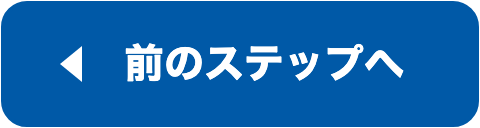](matlab:open('Part6_OptimalPowerFlow.mlx'))　　[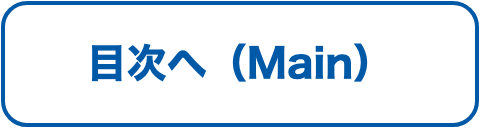](matlab:open('Main.mlx'))　　[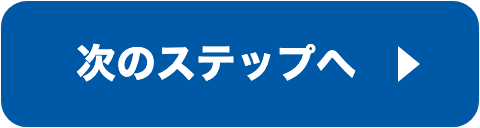](matlab:open('Part8_ControllerDesign.mlx'))

## 付録: 縮約したヤコビアンを作る関数

5 節で使った関数です。母線電圧 `cv_V`、アドミタンス行列 `cm_Y`、slack 以外の母線 `lv_ns`、PQ 母線 `lv_PQ` から、5 節の式で $J_\mathrm{R}$ を作ります。

function rm_JR = reduced_jacobian(cv_V, cm_Y, lv_ns, lv_PQ)
    cv_I = cm_Y * cv_V;                                     % 注入電流 I = Y V
    cm_dSdth = 1i * diag(cv_V) * conj(diag(cv_I) - cm_Y * diag(cv_V));
    cm_dSdV = diag(cv_V) * conj(cm_Y * diag(cv_V ./ abs(cv_V))) + conj(diag(cv_I)) * diag(cv_V ./ abs(cv_V));
    rm_JPth = real(cm_dSdth(lv_ns, lv_ns));
    rm_JPV  = real(cm_dSdV(lv_ns, lv_PQ));
    rm_JQth = imag(cm_dSdth(lv_PQ, lv_ns));
    rm_JQV  = imag(cm_dSdV(lv_PQ, lv_PQ));
    rm_JR = rm_JQV - rm_JQth * (rm_JPth \ rm_JPV);
end